clear
clc

dataset = load("GroupTesting.mat");
data = dataset.x;

seed = 42;
rng(seed);

p_size = 35;
m_size = 100;
x_size = 10;

% comp_hamming = zeros(m_size,p_size);
% dd_hamming =zeros(m_size,p_size);
% scomp_hamming =zeros(m_size,p_size);
lp_hamming =zeros(m_size,p_size);

% T_comp = 0;
% T_dd = 0;
% T_scomp = 0;
T_lp = 0;


tStart = tic;

parfor p=1:p_size
% ["prob: ", p/100]
    A_ori = rand(100,100);
    A_ori(A_ori > 1-p/100) = 1;
    A_ori(A_ori <= 1-p/100) = 0;
    for i=1:x_size
        x = data(i,:)';
        y_ori = sign(A_ori*x);
        pos_test_ = find(y_ori==1);
        pos_size_ = size(pos_test_);
        neg_test_ = find(y_ori==0);
        neg_size_ = size(neg_test_);

        for m=1:m_size
            A = A_ori(1:m,:);
            pos_test = pos_test_(pos_test_ <=m);
            neg_test = neg_test_(neg_test_ <=m);

            % tic
            % comp_hamming(m,p) = comp_hamming(m,p) +...
            %     Comp(neg_test,A, x);
            % T_comp = T_comp + toc;
            % 
            % tic
            % dd_hamming(m,p) = dd_hamming(m,p) +...
            %     DD(pos_test, neg_test, A, x);
            % T_dd = T_dd + toc;
            % 
            % tic
            % scomp_hamming(m,p) = scomp_hamming(m,p) +...
            %     Scomp(pos_test, neg_test, A, x);
            % T_scomp = T_scomp +toc;

            tic
            lp_hamming(m,p) = lp_hamming(m,p) +...
                LP_func(pos_test, neg_test, A, x);
            T_lp = T_lp +toc;

        end
    end
end

tEnd = toc(tStart);

% comp_hamming = comp_hamming/x_size;
% dd_hamming = dd_hamming/x_size;
% scomp_hamming = scomp_hamming/x_size;
lp_hamming = lp_hamming/x_size;


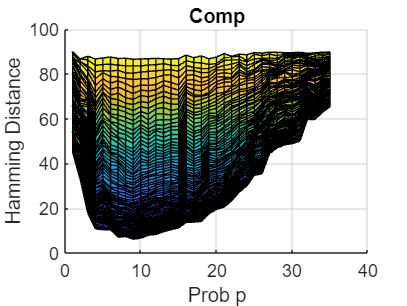

surf(comp_hamming(1:70,:))
ylabel('#tests m'), xlabel('Prob p'), zlabel('Hamming Distance')
title("Comp")
view([0 0])

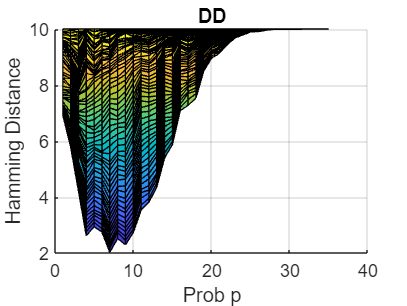


surf(dd_hamming(1:70,:))
ylabel('#tests m'), xlabel('Prob p'), zlabel('Hamming Distance')
title("DD")
view([0 0])

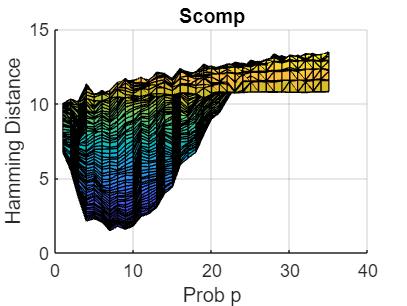


surf(scomp_hamming(1:70,:))
ylabel('#tests m'), xlabel('Prob p'), zlabel('Hamming Distance')
title("Scomp")
view([0 0])

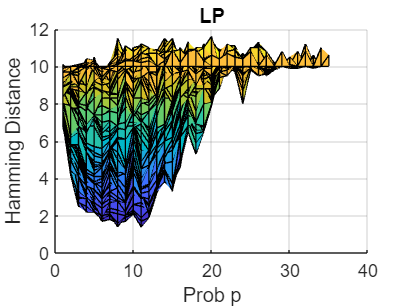


surf(lp_hamming(1:70,:))
ylabel('#tests m'), xlabel('Prob p'), zlabel('Hamming Distance')
title("LP")
view([0 0])

% Initial data
x = dataset.x(1,:);
x = x';
pos = sum(x);

% Parameters
p = 0.1;   % probability of 1 in measurement A
m = 50;     % #of measurements
seed = 42;
rng(seed);

% Generating A with probability p
A = rand(m,100);
A(A>1-p) = 1;
A(A<=1-p) = 0;

y_ori = A*x;
y = zeros(size(y_ori));
y(y_ori>0) = 1;

% Positive and negative tests
pos_test = find(y==1);
pos_size = length(pos_test);
neg_test = find(y==0);
neg_size = length(neg_test);

% Comp (Combinatorial Orthogonal Matching Persuit)
% This is largest satisfying set
comp.x = ones(size(x));
for i=1:neg_size
    j = neg_test(i);
    comp.x(A(j,:)>0)=0;
end
comp.positives = sum(comp.x);
comp.distance = sum((comp.x-x).^2);

% DD
dd.x = ones(size(x))/2;
for i=1:neg_size
    j = neg_test(i);
    dd.x(A(j,:)>0)=0;
end

for i=1:pos_size
    j = pos_test(i);
    if (A(j,:)*dd.x==0.5)
        idx = and(dd.x, A(j,:)');
        dd.x(idx==1)=1;
    end
end

dd.PD = zeros(size(x));
dd.PD = dd.x(dd.x<1);
dd.PD(dd.PD>0)=1;
dd.x(dd.x<1)=0;


if A*dd.x == y
    dd.outcome = "Satisfying set";
else
    dd.outcome = "No Satisfying set";
end
dd.positives = sum(dd.x);
dd.distance = sum((dd.x-x).^2);

dd

dd = struct with fields:
            x: [100×1 double]
           PD: [96×1 double]
      outcome: "No Satisfying set"
    positives: 4
     distance: 6


% SCOMP
% Initialize 
scomp.x = zeros(size(x));
x_temp = ones(size(x))*0.1; % set all to uncertain

% Set negatives to 0
for i=1:neg_size
    j = neg_test(i);
    x_temp(A(j,:)>0)=0;
end

% If there is only 1 uncertain in pos, set to 1
for i=1:pos_size
    j = pos_test(i);
    if (A(j,:)*x_temp==0.1)    % only 1 uncertain in test
        idx = and(x_temp, A(j,:)');
        x_temp(idx==1)=1;
        scomp.x(idx==1)=1;     % set to def_pos
    end
end

% Create list of uncertain tests
scomp.unc_test=[];
for i=1:pos_size
    j = pos_test(i);
    if (A(j,:)*scomp.x==0)    % no def_pos in test
        scomp.unc_test(end+1)=j;
    end
end


scomp.unexplained = zeros(size(x));
scomp.unexplained(x_temp==0.1) = 0.1;
% Search for most common x in unexplained tests
while sum(scomp.unc_test)>0
    for i=1:size(scomp.unc_test,2)
        j=scomp.unc_test(i);
        scomp.unexplained = scomp.unexplained + ...
            and(scomp.unexplained, A(j,:)')/10;
    end
    % Add most common to def_pos
    [~,idx] = max(scomp.unexplained);
    scomp.x(idx)=1;
    scomp.unexplained(idx) = 0;
    scomp.unexplained(scomp.unexplained>0) = 0.1;

    % Check for explained tests
    for i=size(scomp.unc_test,2):-1:1
        j = scomp.unc_test(i);
        if (A(j,:)*scomp.x > 0)    % def_pos in test
            scomp.unc_test(scomp.unc_test==j)=[];
        end
    end

end

scomp.positives = sum(scomp.x);
scomp.distance = sum((scomp.x-x).^2);
scomp

scomp = struct with fields:
              x: [100×1 double]
       unc_test: [1×0 double]
    unexplained: [100×1 double]
      positives: 8
       distance: 4


N=100;
m=50;
pos_test = find(y==1);
pos_size = length(pos_test);
neg_test = find(y==0);
neg_size = length(neg_test);


cvx_begin
    variable z(N,1)
    minimize( norm(z,1))
    subject to
    for i=1:pos_size
        j = pos_test(i);
         A(j,:)*z >= 1;
    end

    for i=1:neg_size
        j = neg_test(i);
         A(j,:)*z == 0;
    end
    for i=1:100
        % z(i)<=1;
        z(i)>=0;
    end
cvx_end

 
Calling SDPT3 4.0: 337 variables, 150 equality constraints
------------------------------------------------------------

 num. of constraints = 150
 dim. of socp   var  = 200,   num. of socp blk  = 100
 dim. of linear var  = 137
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.0e+01|1.5e+01|2.0e+04| 1.414214e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.807|0.419|3.8e+00|9.0e+00|1.0e+04| 5.086799e+02  9.250830e+00| 0:0:01| chol  1  1 
 2|0.655|0.783|1.3e+00|2.0e+00|3.2e+03| 5.443514e+02  6.547758e+00| 0:0:01| chol  1  1 
 3|0.855|0.954|1.9e-01|9.2e-02|5.2e+02| 3.143059e+02  4.917721e+00| 0:0:01| chol  1  1 
 4|0.9


z = round(z);

if A*z == y
    LP.outcome = "Satisfying set";
else
    LP.outcome = "No Satisfying set";
end


LP.positives = sum(z);
LP.distance = sum((z-x).^2);

LP

LP = struct with fields:
      outcome: "No Satisfying set"
    positives: 7
     distance: 3


comp
dd
scomp